## Load Data

clc
clear all
close all

[s1, fs] = audioread('clean_speech.wav');                   % Source 1
[s2, ~]  = audioread('clean_speech_2.wav');                 % Source 2
[n1, ~]  = audioread('aritificial_nonstat_noise.wav');      % Artificial non-stationary noise
[n2, ~]  = audioread('babble_noise.wav');                   % Babble noise
[n3, ~]  = audioread('Speech_shaped_noise.wav');            % Speech shaped noise
load('impulse_responses.mat');                              % 5 impulses for 4 microphone each
hs = {h_inter1, h_inter2, h_inter3, h_inter4, h_target};

## Visualize Room Responses

t = 1:length(h_inter1(1, :)); t = t / fs;
ymin = inf;
ymax = -inf;
for i = 1:5
    for j = 1:4
        data = hs{i}(j, :);
        ymin = min(ymin, min(data));
        ymax = max(ymax, max(data));
    end
end

figure;
for i = 1:5  % Room responses (rows)
    for j = 1:4  % Microphones (columns)
        idx = (i - 1) * 4 + j;  % Convert (i,j) to subplot index
        subplot(5, 4, idx);
        plot(t, hs{i}(j, :));  % Replace with appropriate plotting code
        title(sprintf('Room %d - Mic %d', i, j));
        xlabel('Time (s)');
        ylabel('Amplitude');
    end
end

## Clip signals

N = min([length(s1), length(s2), length(n1), length(n2), length(n3)]);      % Number of samples for each signal
s1 = s1(1:N); s2 = s2(1:N);                                                 % Clip source signals
n1 = n1(1:N); n2 = n2(1:N); n3 = n3(1:N);                                   % Clip noise signals

## Obtain Received Signals at Microphones

Here we choose a target signal and the remaining (possibly except clean signal 2) signals as interferers.

M = 4;                                                              % Number of microphones                                          
x = zeros(N, M);                                                    % Received signals
SNR_db = 0;                                                         % If desired, decide on noise levels
noise_signals = {n1, n2, n3};                                       % Chosen noise signals (can choose the other clean signal 2 as well)


for m = 1:M % Obtain received signals at each microphone

    % Noise components
    for noise_index = 1:length(noise_signals) % Loop through each noise component to add
        noise_signal = noise_signals{noise_index};                  % Noise signal
        room_response = squeeze(hs{noise_index}(m, :));             % Room response for current microphone and noise source
        noise_comp = conv(noise_signal, room_response, "same");     % Convolve with the room response
        x(:,m) = x(:, m) + noise_comp;                              % Mic signal
    end
    
    % Signal component
    clean_signal = s1;                                              % Clean signal
    room_response = squeeze(hs{5}(m, :));                           % Room response for current micrphone and signal source
    signal_comp = conv(clean_signal, room_response, "same");        % Convolve with the room response
    x(:,m) = x(:, m) + signal_comp;                                 % Mic signal
end
       
p = play_scaled_sound(x(:, 1), fs); % Uncomment if you want to listen to the received signal at the first microphone
% stop(p); % If you want to stop playing

## Take STFT

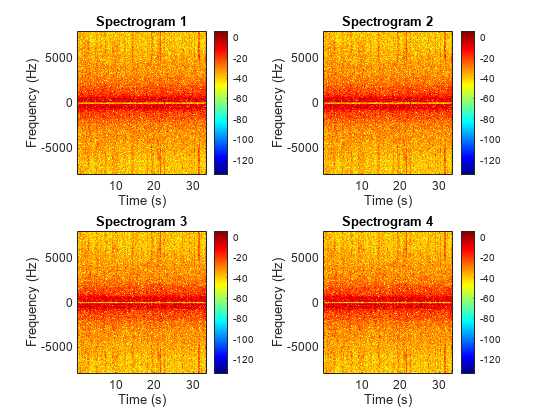

win_len = 512;                                                      % Corresponds to 32ms (can be considered stationary)                                                   
overlap = win_len / 2;                                              % 50% overlap
nfft = 512;                                                         % 512 point fft
win = sqrt(hann(win_len, 'periodic'));                              % To avoid edge artifacts

for m = 1:M
    [X(:,:,m), f, t] = stft(x(:,m), fs, 'Window', win, 'OverlapLength', overlap, 'FFTLength', nfft);
end
[K, L] = size(X(:,:,1));  % frequency bins x time frames
plot_spectrograms(X, t, f);

#### Check clean signal's representation at mic4 to determine silent period

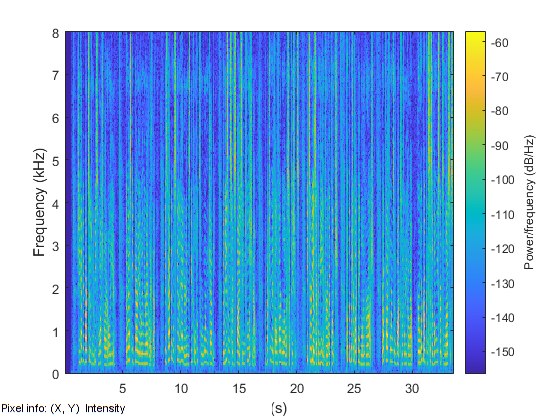

figure;
spectrogram(signal_comp, win, overlap, nfft, fs, 'yaxis');
impixelinfo();

## Estimate Noise Spatial Covariance Assuming Ergodicity

R_n = zeros(K, M, M);
n_silent_time_bins = floor(0.4 * fs / 512) ; % First 0.4 seconds is silent

% Rn is 512x4x4 (frequency bins(DFT) x channels x channels)
% estimating the noise covariance matrix based on the first n_silent_time_bins 
% frames for each frequency band
for k = 1:K
    for l = 1:n_silent_time_bins                            % First n_silent_time_bins frames
        x_k = squeeze(X(k,l,:));                            % Mx1
        R_n(k,:,:) = squeeze(R_n(k,:,:)) + (x_k * x_k');
    end
    R_n(k,:,:) = squeeze(R_n(k,:,:)) / n_silent_time_bins;
end

## Estimate Received Signal Spatial Covariance Assuming Stationarity in a Band

R_x = zeros(K, M, M);
% Rx is 512x4x4 (frequency bins(DFT) x channels x channels)
for k = 1:K
    for l = n_silent_time_bins+1:L                          % Skip silent period
        x_k = squeeze(X(k,l,:));                            % Mx1
        R_x(k,:,:) = squeeze(R_x(k,:,:)) + (x_k * x_k');
    end
    R_x(k,:,:) = squeeze(R_x(k,:,:)) / L;
end

## Obtain RTF (Ground truth)

A_s = zeros(K, M);
for m = 1:M
    A_m = fft(hs{5}(m, :), K); 
    A_s(:, m) = A_m;                 
end
A_s = A_s ./ A_s(:, 1);

## Estimate RTF

A_hats = zeros(K, M);                   % Estimated RTF per frequency band
for k = 1:K
    R_x_k = squeeze(R_x(k, :, :));
    R_n_k = squeeze(R_n(k, :, :));
    [U, D] = gevd(R_x_k, R_n_k);        % Generalized eigenvalue decomp, colums of U are the right eigenvectors
    Q = inv(U)';
    A_hats(k, :) = Q(:, 1) / Q(1, 1);   % Normalize with the first element
end


## MVDR

for k = 1:K
    Rnk = squeeze(R_n(k,:,:));
    ak = A_hats(k,:).'; 
    
    % MVDR weights
    w_mvdr = (Rnk \ ak) / (ak' / Rnk * ak); 
    
    for l = 1:L
        x_k = squeeze(X(k,l,:));
        S_hat(k,l) = w_mvdr' * x_k;
    end
end
y = istft(S_hat, fs, 'Window', win, 'OverlapLength', overlap, 'FFTLength', nfft);


### Results

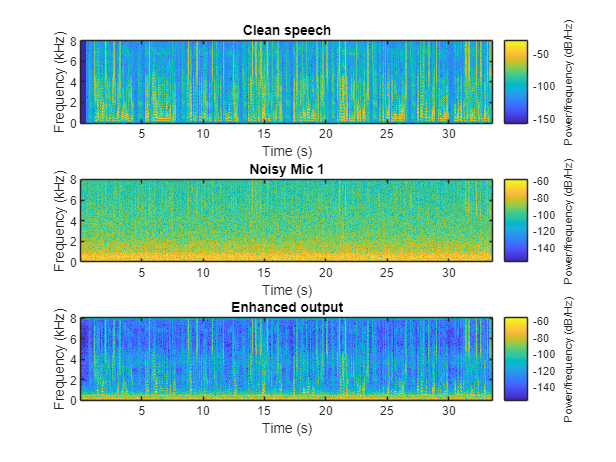

p = play_scaled_sound(y, fs);
audiowrite('enhanced_mvdr.wav', y, fs);
figure;
subplot(3,1,1); spectrogram(s1, win, overlap, nfft, fs, 'yaxis'); title('Clean speech');
subplot(3,1,2); spectrogram(x(:,1), win, overlap, nfft, fs, 'yaxis'); title('Noisy Mic 1');
subplot(3,1,3); spectrogram(y, win, overlap, nfft, fs, 'yaxis'); title('Enhanced output');